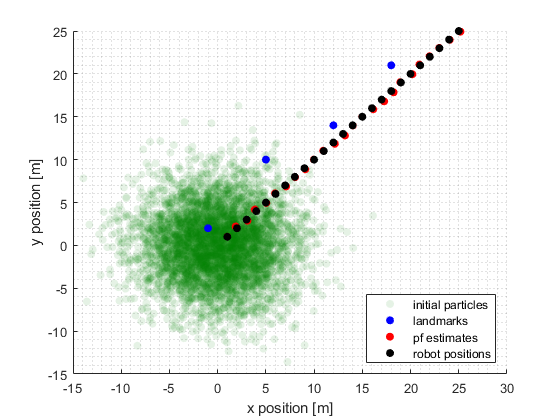

clear variables; close all; clc

% particle filter example
% tracking of a robot
% states = (position x, position y, orientation theta) = (x, y, theta)'
% measures = (range, bearing)'
% control inputs = (commanded velocity, steering angle) =  (v, alpha)'

addpath('../utilities');

% time step [s]
dt = 1;

% number of particles
N = 5000;

% number of input commands
n = 25;

% landmarks information
landmarks = [-1 2; 5 10; 12 14; 18 21]';

% dimensions
dim_lms = size(landmarks, 2);
dim_x = 3;
dim_z = 2 * dim_lms;
dim_u = 2;

% input commands information
commands = ones(dim_u, n).*[1.414, 0]';

% robot information
wheelbase = 0.5;
robot_pos = [0, 0, pi/4]';

% sensor noise std (range, bearing)
std_R = [0.1, 0];

% process noise std
std_Q = [0.05, 0.2];

% data structures
track = zeros(dim_x, n);
x_posterior = zeros(dim_x, n);
P_posterior = cell(1, n);
part_posterior = cell(1, n);

neff = @(weights) 1/vecnorm(weights)^2;
all_close = @(a, b, rtol, atol) assert(all(abs(a - b) <= (atol + rtol * abs(b))));
 
% draw from px0
mu0 = [0 0 pi/4]';
sigma0 = [4 4 0]';
particles = gaussian_particles(N, mu0, sigma0);
particles(3, :) = mod(particles(3, :), 2*pi);
weights = ones(N, 1) / N;

% saving
part_init = particles;

% filtering
for tt = 1:n
    u = commands(:, tt);
    
    % simulate new robot position (x, y, theta)
    robot_pos = robot_move(robot_pos, u, dt, wheelbase);
        
    % build observations/measures
    z = robot_measure(robot_pos, landmarks, std_R(1), std_R(2), dim_z);
    
    % only range
    z = z(1:2:end);
    
    % adaptive resampling
    if neff(weights) < (0.5 * N)
        % multinomial resampling
        indexes = multinomial_sampling(weights, N);
        
        % resample from indexes
        particles(:) = particles(:, indexes);
        weights(:) = 1/N;
    end
    
    % propagation (predict)
    particles = predict_robot(particles, u, dt, std_Q);

    % weighting (update)
    %     for ii = 1 : N
    %         dist = vecnorm(particles(1:2, ii) - landmarks);
    %         weights(ii) = prod(normpdf(z, dist', std_R(1)));
    %     end
    for ii = 1:dim_lms
        dist = vecnorm(particles(1:2, :) - landmarks(:, ii));
        weights = weights .* normpdf(z(ii), dist, std_R(1))';
    end

    % normalization
    weights = weights / sum(weights);
    
    % estimate    
    [x, P] = pf_estimate(particles, weights);       
  
    % saving
    track(:, tt) = robot_pos;
    x_posterior(:, tt) = x;
    P_posterior{tt} = P;
    part_posterior{tt} = particles;
end

figure
hold on; grid minor;
scatter(part_init(1, :), part_init(2, :), 36, [0 0.5 0], 'filled', 'MarkerFaceAlpha', 0.1)
scatter(landmarks(1, :), landmarks(2, :), 'b', 'filled');
scatter(x_posterior(1, :), x_posterior(2, :) ,'r', 'filled');
scatter(track(1, :), track(2, :), 'k', 'filled', 'LineWidth', 2);
xlabel('x position [m]');
ylabel('y position [m]')
legend('initial particles' , 'landmarks', 'pf estimates', 'robot positions', 'location', 'southeast')

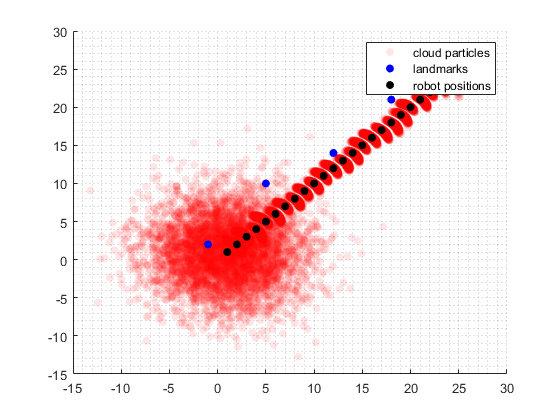

figure
hold on; grid minor;
p = part_posterior{1};
h1 = scatter(p(1, :), p(2, :), 'r', 'filled', 'MarkerFaceAlpha', 0.1);
for tt = 2:n
    p = part_posterior{tt};
    scatter(p(1, :), p(2, :), 'r', 'filled', 'MarkerFaceAlpha', 0.1);
end
h2 = scatter(landmarks(1, :), landmarks(2, :), 'b', 'filled');
h3 = scatter(track(1, :), track(2, :), 'k', 'filled', 'LineWidth', 2);
legend([h1 h2 h3], {'cloud particles', 'landmarks', 'robot positions'})